%Name: Martins Davis Bernhards 
%Student number: 552135
%Assignments week 4 


%Assignment 1

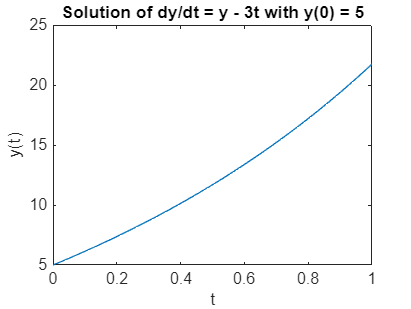

t = linspace(0, 1, 100);

% Analytical solution to the differential equation
y = 3*t - 3 + 8*exp(t);

% Plot the solution
plot(t, y);
xlabel('t');
ylabel('y(t)');
title('Solution of dy/dt = y - 3t with y(0) = 5');

%Assignment 2

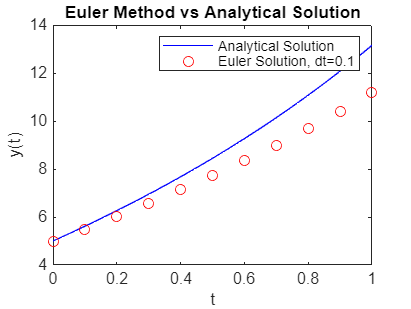

% Time parameters
t0 = 0;
t_end = 1;
dt = 0.1;
y0 = 5;

% Analytical solution
t_analytical = linspace(t0, t_end, 100);
y_analytical = 3 * t_analytical + 2 + 3 * exp(t_analytical);

% Euler method
[t_euler, y_euler] = Euler(@righthandside, t_end, dt, t0, y0);

% Plot Euler and analytical solutions
figure;
plot(t_analytical, y_analytical, 'b-', 'DisplayName', 'Analytical Solution');
hold on;
plot(t_euler, y_euler, 'ro', 'DisplayName', 'Euler Solution, dt=0.1');
legend;
xlabel('t');
ylabel('y(t)');
title('Euler Method vs Analytical Solution');
hold off;


% Error Calculation for dt = 0.1, 0.05, 0.025
dt1 = 0.05;
[t_euler1, y_euler1] = Euler(@righthandside, t_end, dt1, t0, y0);

dt2 = 0.025;
[t_euler2, y_euler2] = Euler(@righthandside, t_end, dt2, t0, y0);

% Calculate errors at t=1
error_dt_01 = abs(y_euler(end) - (3 * 1 + 2 + 3 * exp(1)));
error_dt_005 = abs(y_euler1(end) - (3 * 1 + 2 + 3 * exp(1)));
error_dt_0025 = abs(y_euler2(end) - (3 * 1 + 2 + 3 * exp(1)));

% Error ratios
error_ratio1 = error_dt_005 / error_dt_01;
error_ratio2 = error_dt_0025 / error_dt_005;

disp('Error Ratios:');

Error Ratios:


disp(['E(dt=0.05)/E(dt=0.1) = ', num2str(error_ratio1)]);

E(dt=0.05)/E(dt=0.1) = 0.93946


disp(['E(dt=0.025)/E(dt=0.05) = ', num2str(error_ratio2)]);

E(dt=0.025)/E(dt=0.05) = 0.96563


%Assignment 3

quadraticEquation(-3);

Unrecognized function or variable 'quadraticEquation'.

quadraticEquation(5);

x = linspace(-4,4,100);
y = quadraticEquation(x);

figure
plot(x,y);
title('y as a function of x');
xlabel('x');
ylabel('y(x)');

%Assignment 4

a = [1, 2, 4];
b = [2, -3, 1];

[y, txt] = calculateAngle(a, b)

%Assignment 5

x = linspace(-1,5,100);
y = x .* sin(x.^2/10);
dydx = derivative(x, y);

figure
subplot(2,1,1);
plot(x, y);
title('f as a function of x');
xlabel('x');
ylabel('f(x)');

subplot(2,1,2);
plot(x, dydx);
title('dydx as a function of x');
xlabel('x');
ylabel('f''(x)');

%Assignment 6

% Manual calculation for Integral (x^2 + 4x)dx in range 5 to 2
% x^3/3 + 2*x^2  find the anti-derivative

% f(5) = 125/3 + 50 = 275/3
% f(2) = 8/3 + 8 = 32/3

% f(5) - f(2) = (273-32)/3 = 243/3 = 81
% answer is: 81

x_min = 2;
x_max = 5;
number_of_trapeziums = 1;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area1 = trapz(x,f_x) % 85.5 too big

number_of_trapeziums = 2;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area2 = trapz(x,f_x) % 82.1250 closer but also too big

number_of_trapeziums = 99;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area99 = trapz(x,f_x) % 81.0005 Basicaly the correct value, but differs a little bit

number_of_trapeziums = 999;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area999 = trapz(x,f_x) % 81 the correct answer, at least for first 4 decimal digits

%Assignment 7

x_min = 0;
x_max = 2;
number_of_trapeziums = 9;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area10 = trapz(x,f_x) % 1.5882

number_of_trapeziums = 19;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area20 = trapz(x,f_x) % 1.5757

number_of_trapeziums = 39;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area40 = trapz(x,f_x) % 1.58730

number_of_trapeziums = 79;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area80 = trapz(x,f_x) % 1.5723

number_of_trapeziums = 159;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area160 = trapz(x,f_x) % 1.5722

number_of_trapeziums = 319;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area320 = trapz(x,f_x) % 1.5721

number_of_trapeziums = 639;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area639 = trapz(x,f_x) % 1.5721 With 640 the value for first 4 decimal digits doesn't change anymore

%Assignment 8

x_min = 0;
x_max = 2;
f_x = @(x) exp(1-x.^2);

result10 = simpson(f_x,x_min,x_max, 10) % 2.3977

result20 = simpson(f_x,x_min,x_max, 20) % 2.3977 Matches the previous value

%Assignment 9

f_x = @(x) exp(1-x.^2);
integral(f_x,0,2) % 2.3977

%Assignment 10

f_x = @(x) x.^2+4*x;
integral(f_x,2,5) % 81